## Problem 2

- K-Means Clustering

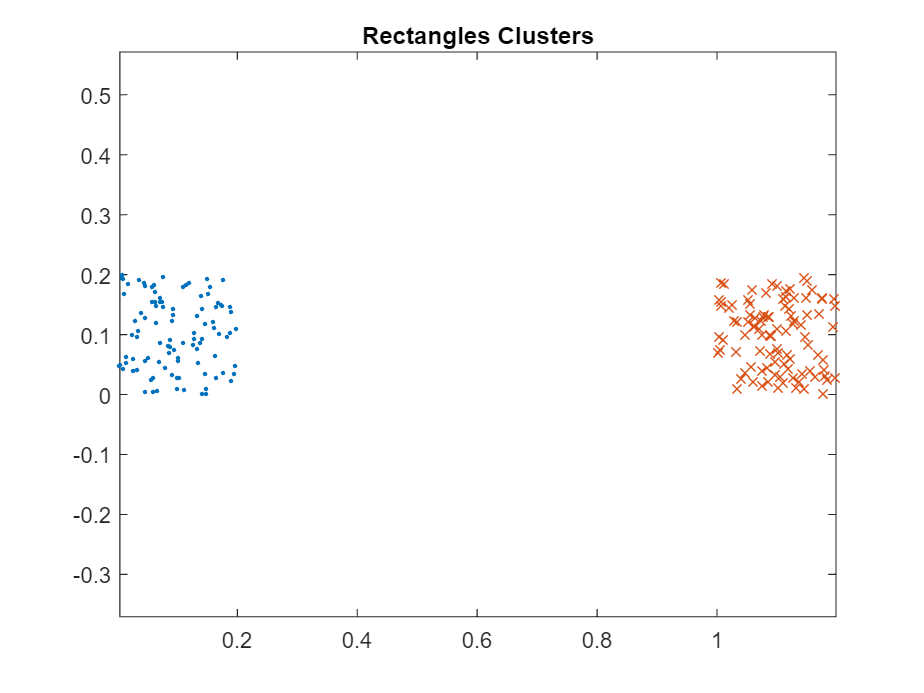

% Load the datasets
load("rectangles.mat"); % loads X2
load("concentric.mat"); % loads X1
load("text.mat");       % loads X4
load("links.mat");      % loads X3

% Perform k-means clustering on each dataset
rect_clusterIdx = kmeans(X2, 2);
conc_clusterIdx = kmeans(X1, 2);
text_clusterIdx = kmeans(X4, 6);
links_clusterIdx = kmeans(X3, 2);

plotClusters(X2, rect_clusterIdx);
title('Rectangles Clusters');

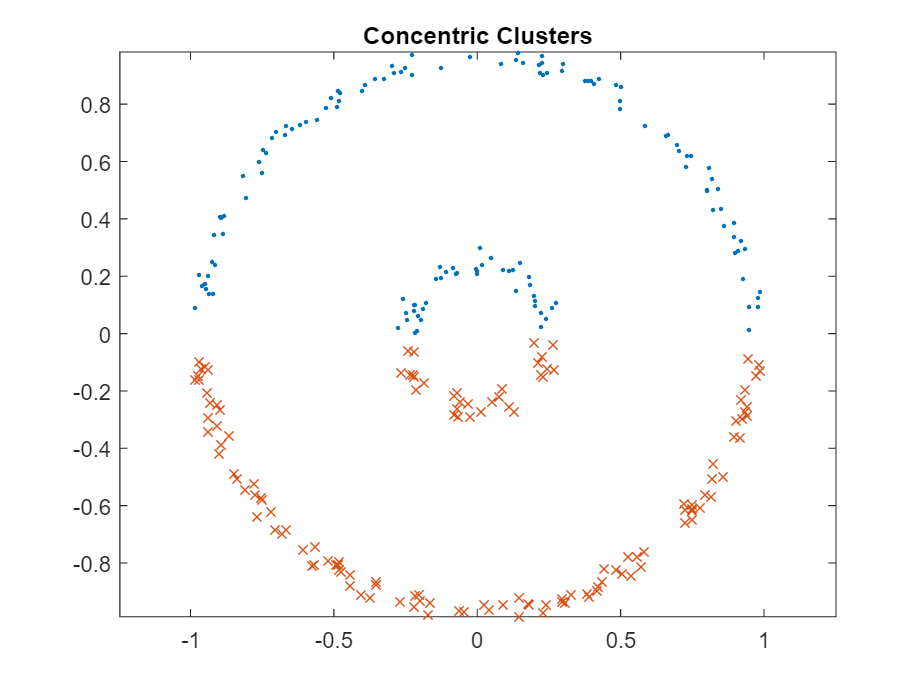

plotClusters(X1, conc_clusterIdx);
title('Concentric Clusters');

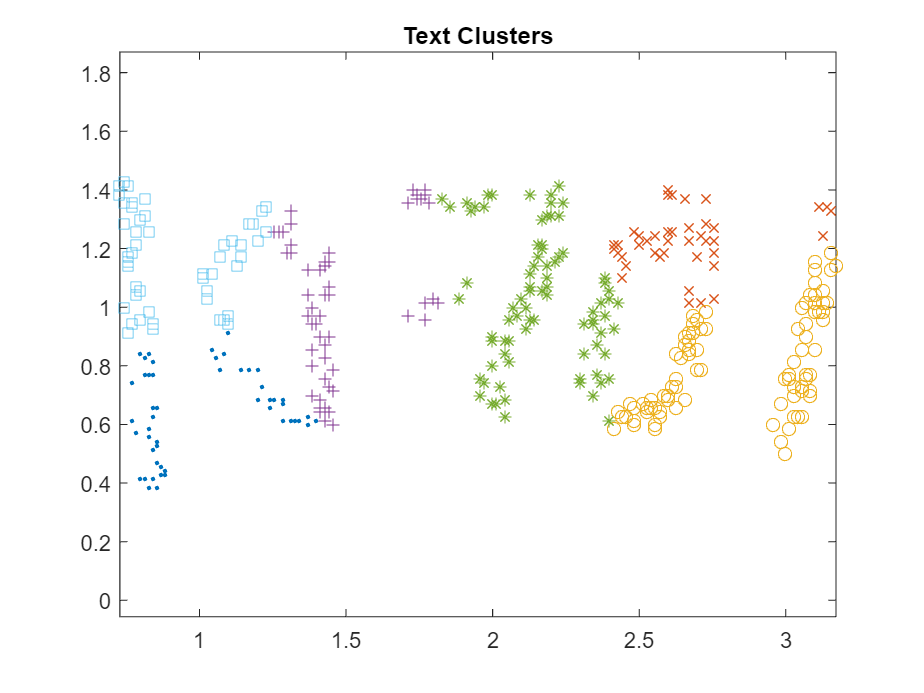

plotClusters(X4, text_clusterIdx);
title('Text Clusters');

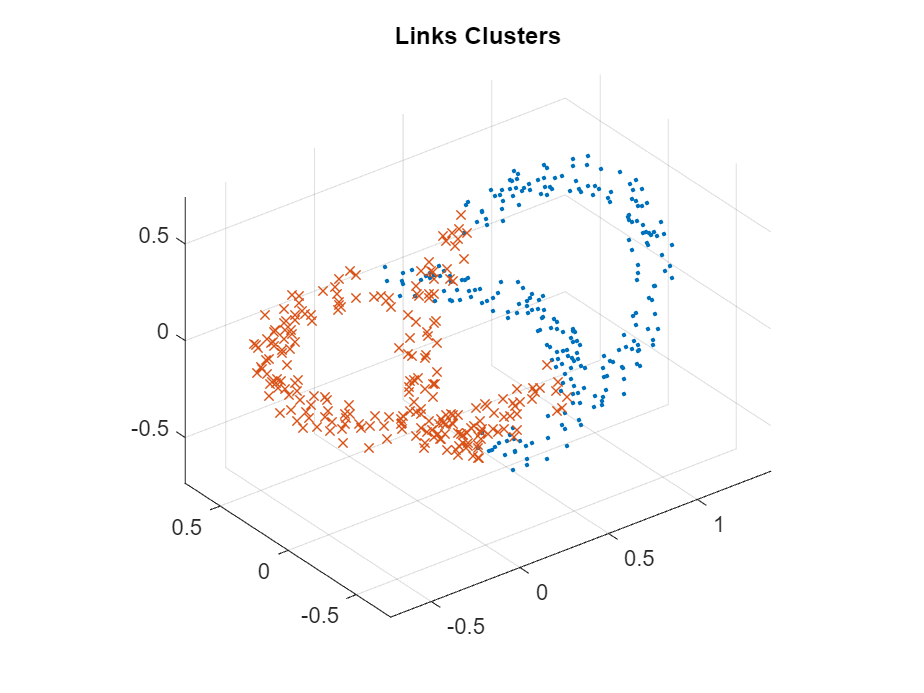

plotClusters(X3, links_clusterIdx);
title('Links Clusters');

2. Implement matrix spectral clustering

ans = 'Plots for sigma: 2.500000e-02'

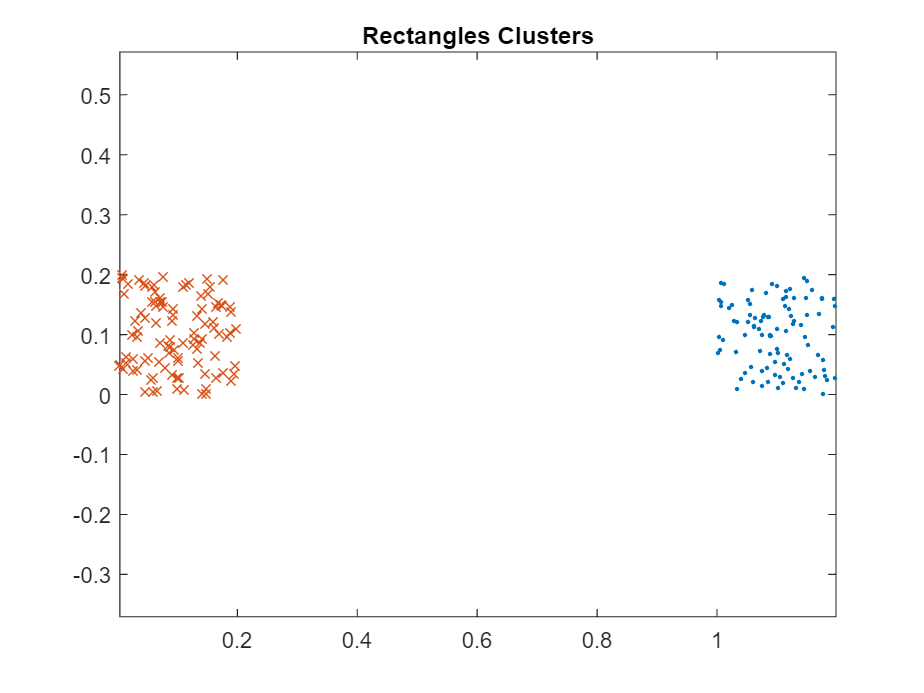

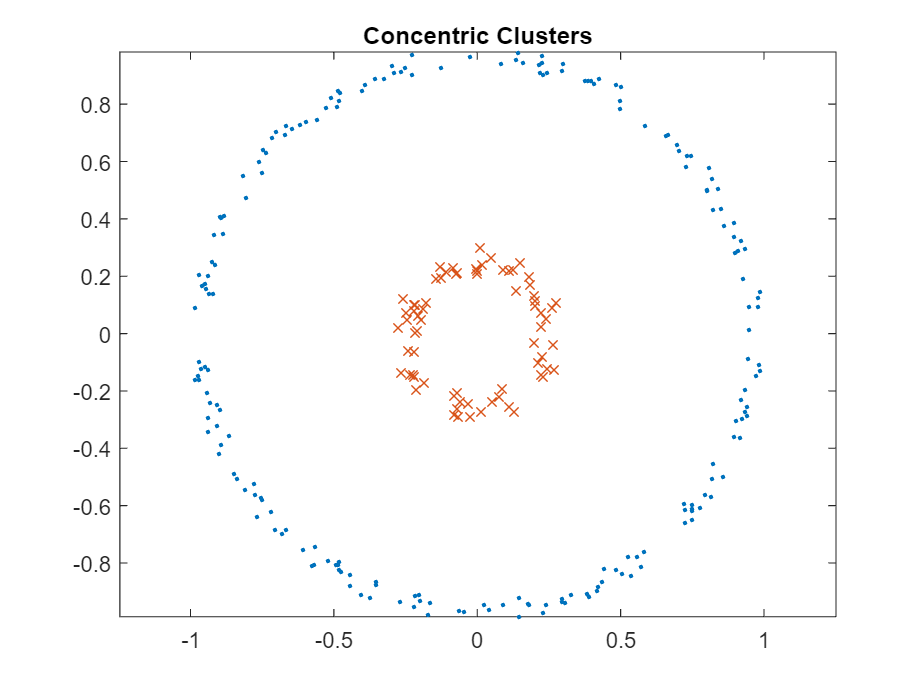

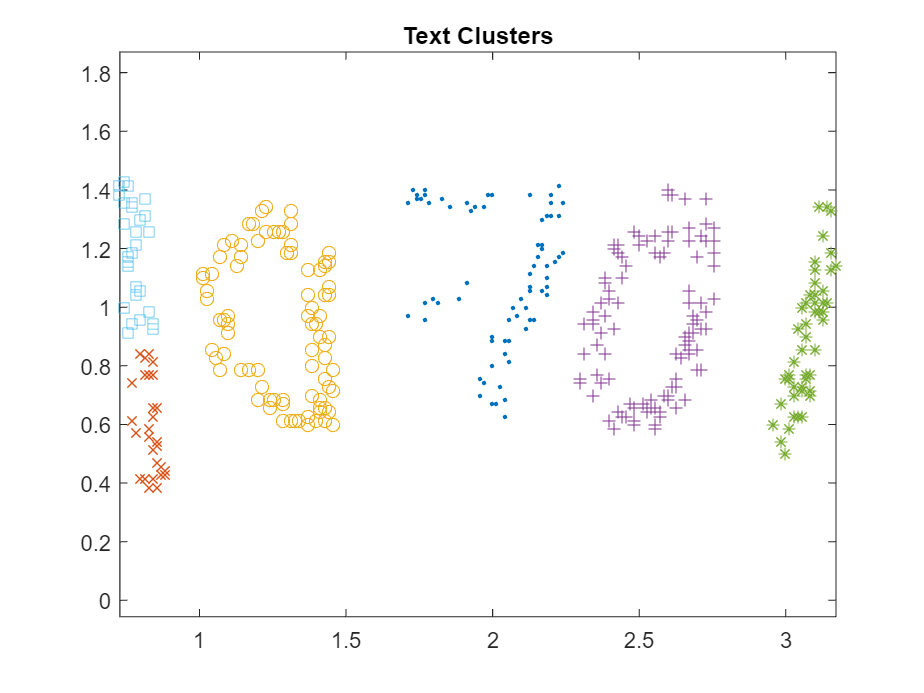

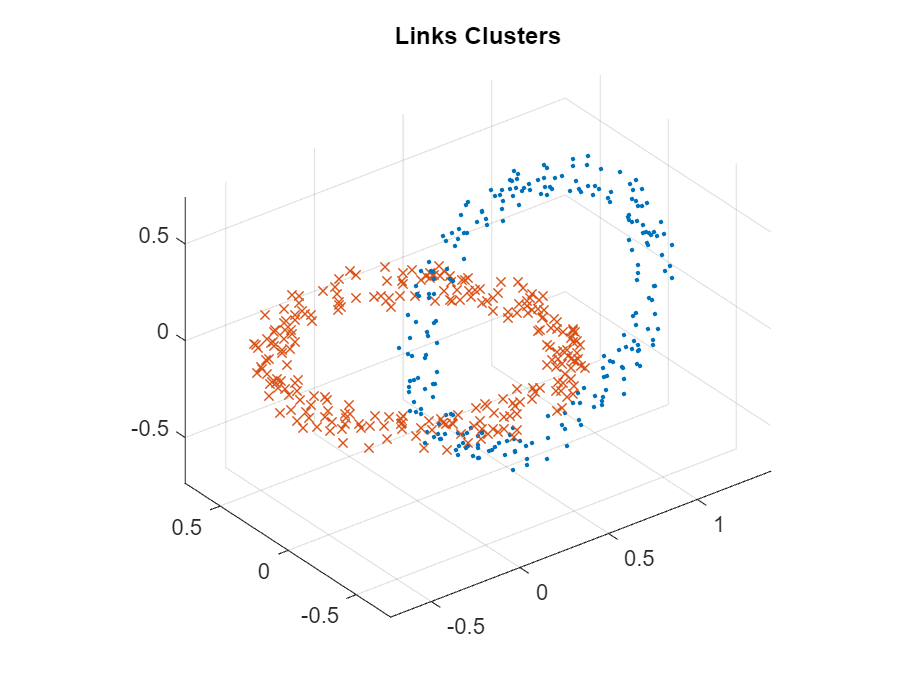

ans = 'Plots for sigma: 5.000000e-02'

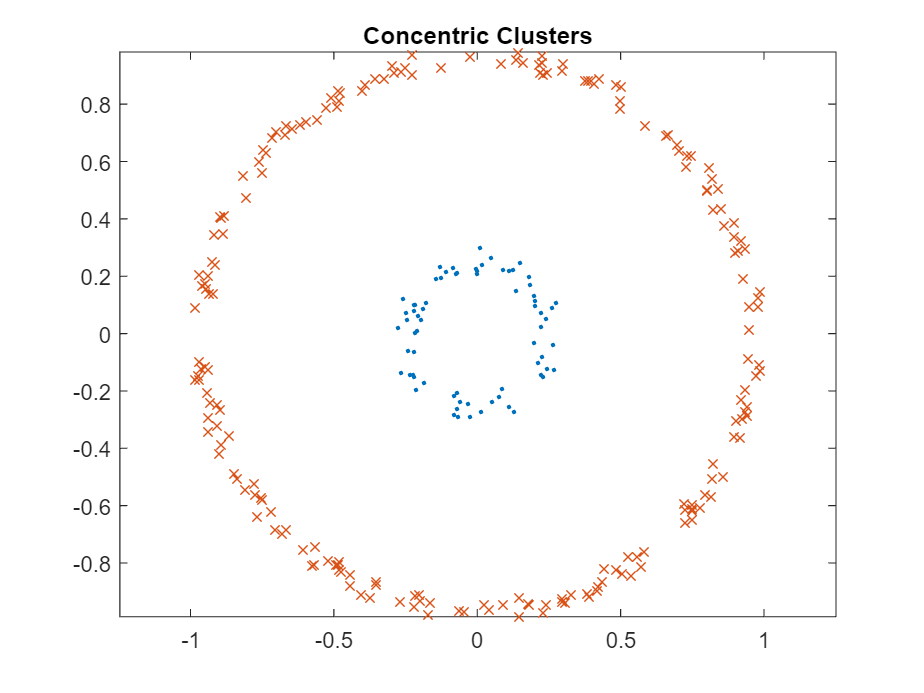

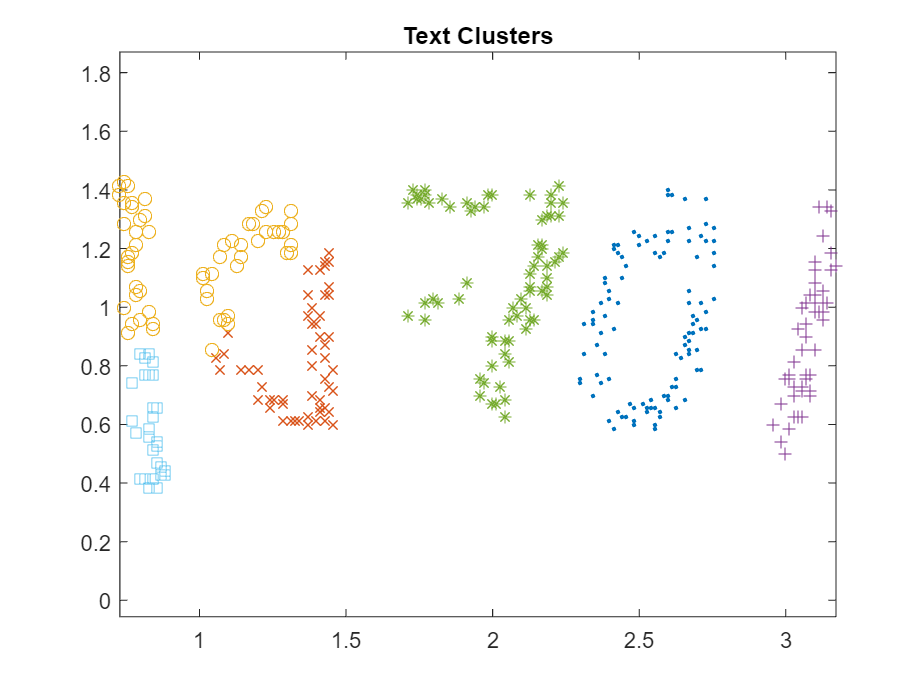

ans = 'Plots for sigma: 2.000000e-01'

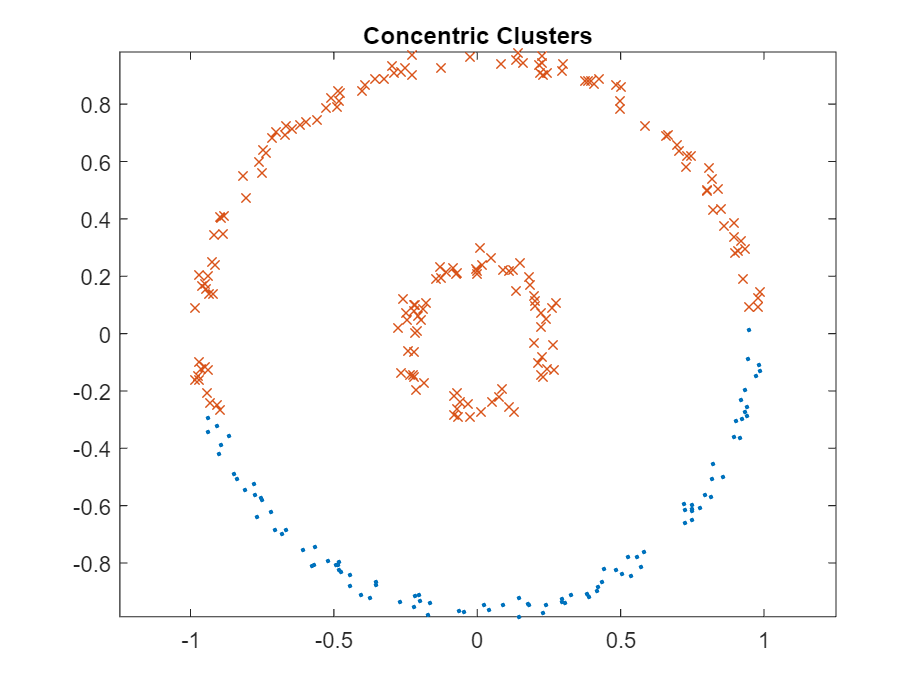

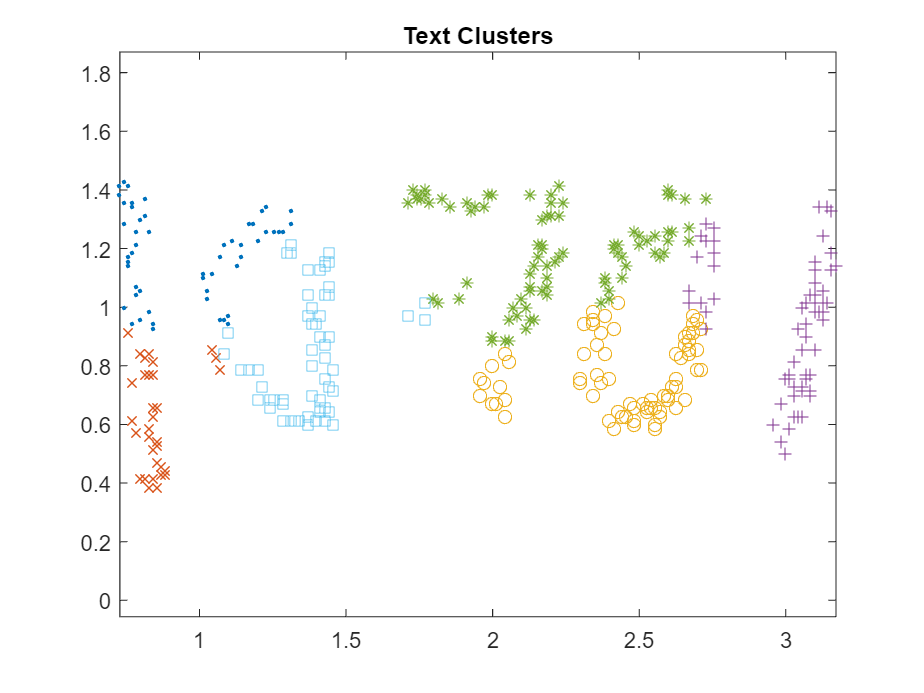

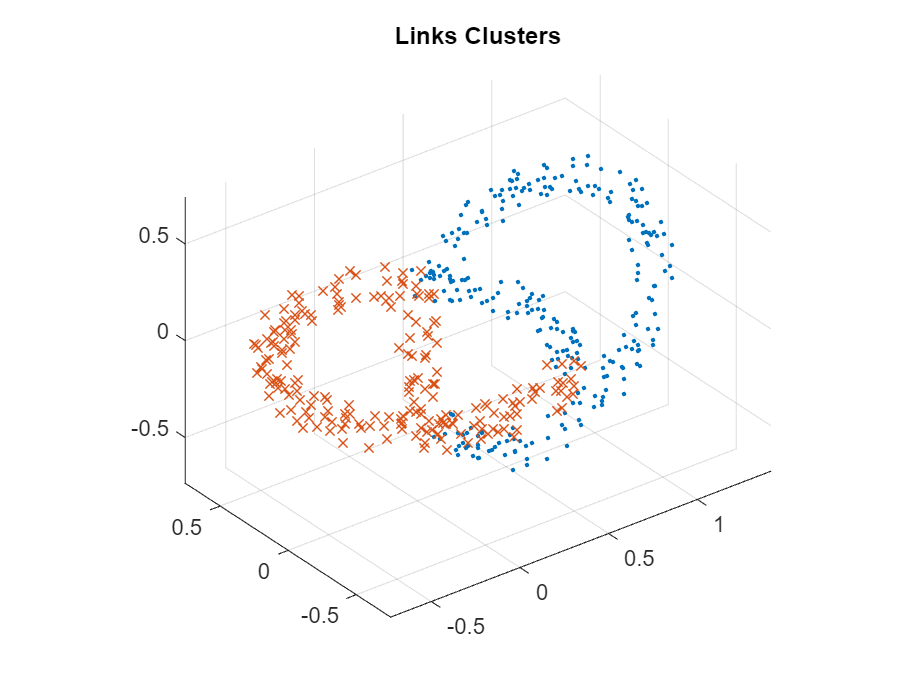

ans = 'Plots for sigma: 5.000000e-01'

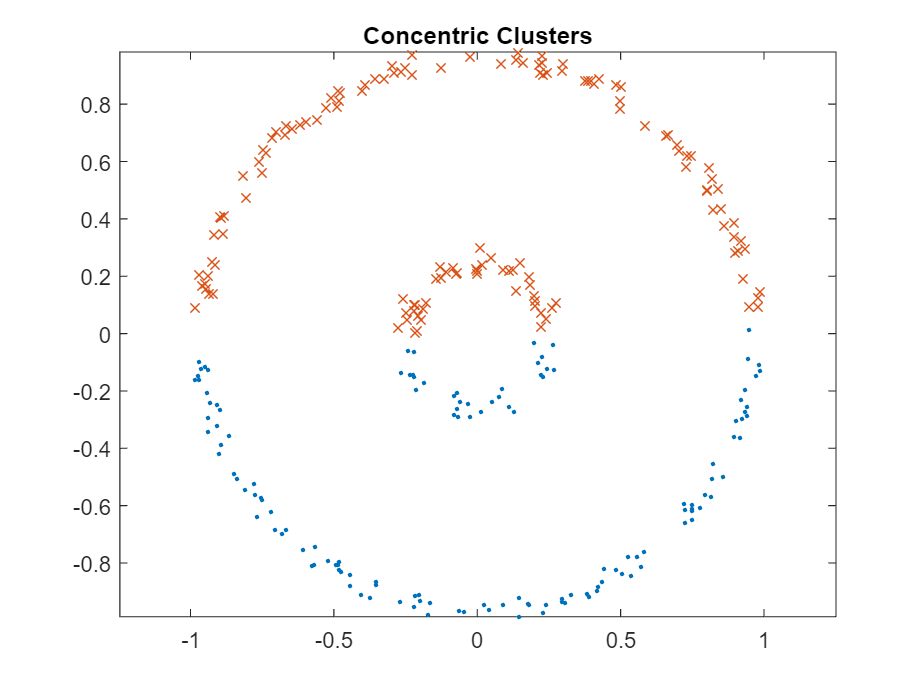

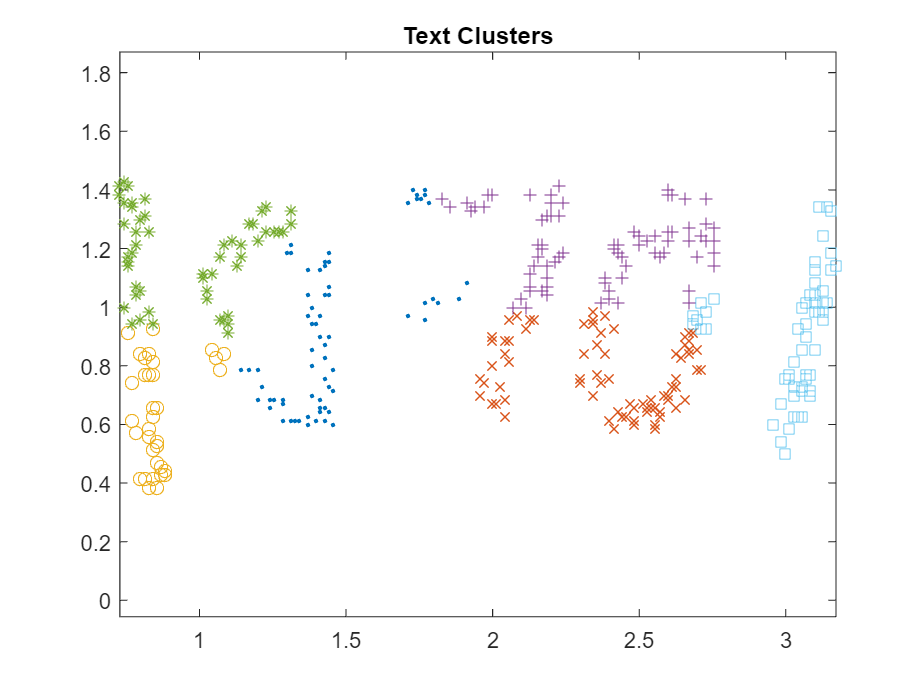

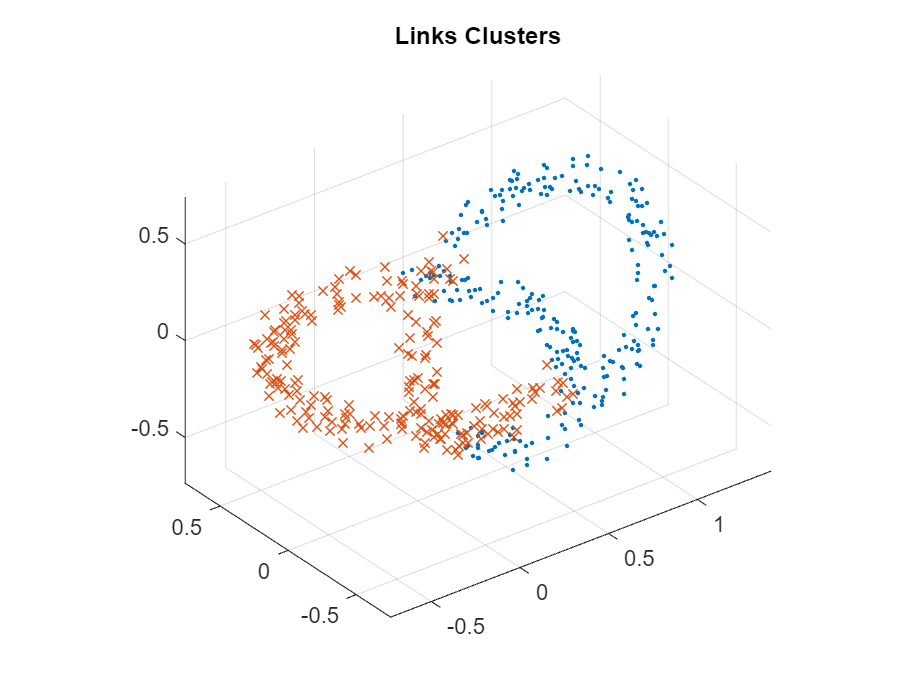

sigma = [.025, .05, .2, .5];
for i = sigma
    [rect_cluster, ~] = clustering(X2, 2, i);
    [conc_cluster, ~] = clustering(X1, 2, i);
    [text_cluster, ~] = clustering(X4, 6, i);
    [links_cluster, ~] = clustering(X3, 2, i);
    
    sprintf('Plots for sigma: %d', i)

    plotClusters(X2, rect_cluster);
    title('Rectangles Clusters');

    plotClusters(X1, conc_cluster);
    title('Concentric Clusters');

    plotClusters(X4, text_cluster);
    title('Text Clusters');

    plotClusters(X3, links_cluster);
    title('Links Clusters');
    
end

3. Plot first 10 Eigenvalues for rectangles.mat and text.mat

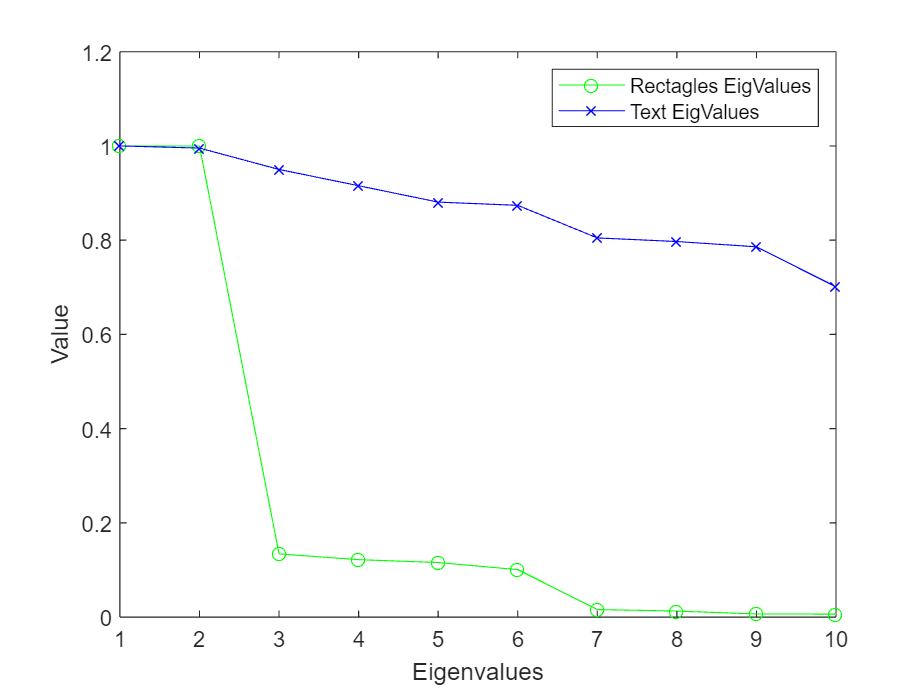

[~, rectangleEigValues] = clustering(X2, 10, .05);
[~, textEigValues] = clustering(X4, 10, .05);

figure;
plot(1:10, diag(rectangleEigValues), 'g-o');
hold on;
plot(1:10, diag(textEigValues), 'b-x');
xlabel("Eigenvalues")
ylabel("Value")
legend('Rectagles EigValues', 'Text EigValues');

ANS

- Rapid Decline in Rectangles Eigenvalues: The eigenvalues for the "Rectangles" dataset drop quickly after the first eigenvalue. This suggests that the first eigenvalue is significantly larger than the others, indicating that there may be one dominant dimension or feature in this dataset.

- Gradual Decline in Text Eigenvalues: The "Text" eigenvalues show a more gradual decline. This implies a more distributed variance across the dimensions or features of the "Text" dataset.

- Difference in Dataset Structures: The different shapes of the curves suggest that the inherent structures of the "Rectangles" and "Text" datasets are quite different. The "Rectangles" dataset may have a simpler or more coherent structure that can be captured by fewer dimensions, whereas the "Text" dataset seems to require more dimensions to capture its variance.

Ques 4) How do K means and Spectral Clustering compare?

Ans) K-means and spectral clustering are fundamentally different clustering techniques. K-means, a distance-based clustering method, assumes that clusters are spherical and is best suited for well-separated data. It's efficient for large datasets but can struggle with non-convex clusters and is sensitive to initial centroid placement. 

Spectral clustering, on the other hand, relies on graph theory, using the eigenvectors of a similarity matrix to reduce dimensionality before clustering. This allows it to detect complex cluster structures that K-means cannot. However, spectral clustering can be computationally intensive, especially for large datasets, due to the eigenvalue decomposition required. 

While K-means excels in computational efficiency and ease of implementation, spectral clustering is more robust in handling data with intricate geometries. The choice between them depends on the specific characteristics of the dataset and the computational resources available.

function [clusters, eigen_Values] = clustering(dataset, k, s)
    
    A = exp(-pdist2(double(dataset), double(dataset), "squaredeuclidean")/s);

    D = diag(1 ./ sqrt(sum(A,2)));
    N = D * A * D;
    
    [eigVectors, eigen_Values] = eigs(N, k, 'largestabs');
    Y = eigVectors;
    
    Y = Y ./ sqrt(sum(Y.^2, 2));

    clusters = kmeans(Y, k);
end